### SUBRGRAFICAS

El comando subplot le permite subdividir la ventana de graficación en una retícula de m filas y n columnas. La función subplot(m, n, p) separa la figura en una matriz m x n. La variable p identifica la porción de la ventana donde se dibujará la siguiente gráfica. 

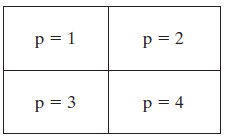

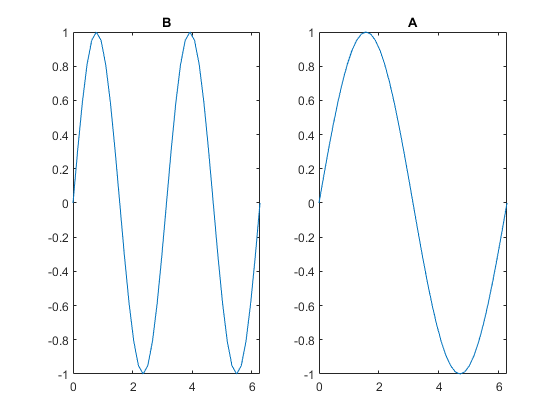

x=0:pi/20:2*pi;

subplot(1,2,2)
plot(x,sin(x))
title("A")

subplot (1,2,1)
plot(x,sin(2*x))
title("B")

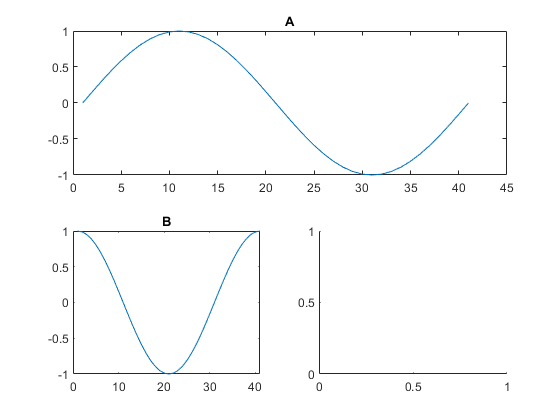

subplot(2,1,1)
plot(sin(x))
title("A")

subplot(2,2,3)

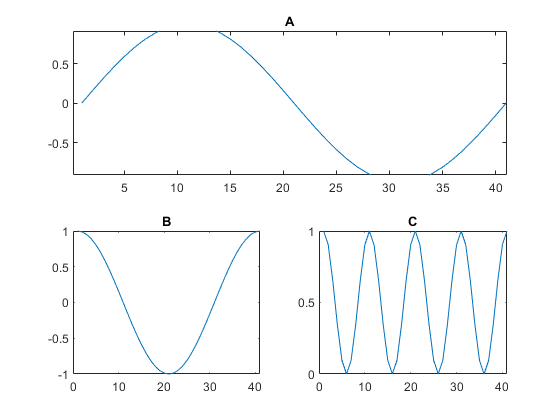

plot(cos(x))
title("B")

subplot(2,2,4)
plot(cos(2*x).^2)
title("C")

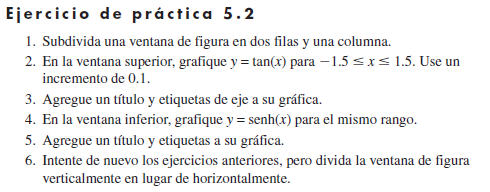

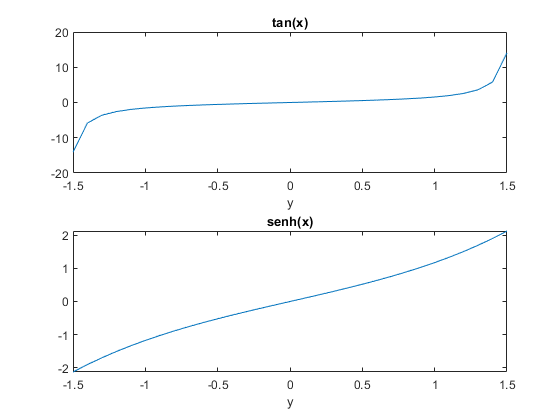

figure
x = -1.5:0.1:1.5;

subplot(2,1,1)
plot(x, tan(x))
title('tan(x)'),xlabel('x'),xlabel('y')

subplot(2,1,2)
plot(x, sinh(x))
title('senh(x)'),xlabel('x'),xlabel('y')

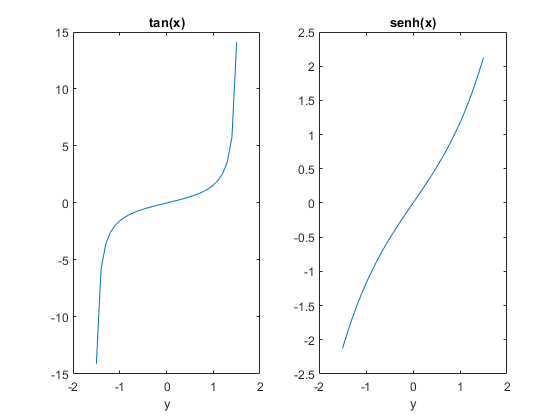

figure
x = -1.5:0.1:1.5;

subplot(1,2,1)
plot(x, tan(x))
title('tan(x)'),xlabel('x'),xlabel('y')

subplot(1,2,2)
plot(x, sinh(x))
title('senh(x)'),xlabel('x'),xlabel('y')

### Gráficas polares

polar(theta, r): Genera una gráfica polar del ángulo theta (en radianes) y distancia radial r.

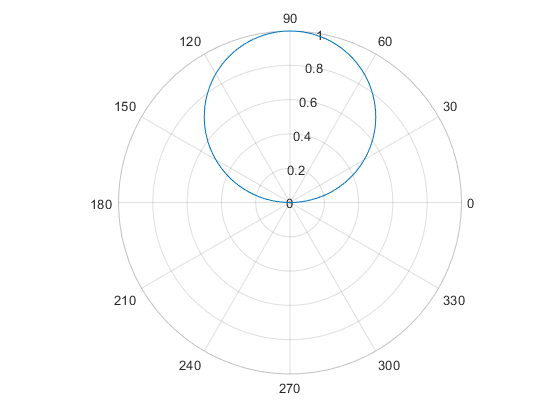

figure()
x = 0:pi/100:pi;
y = sin(x);

polarplot(x,y)

Varias gráficas polares

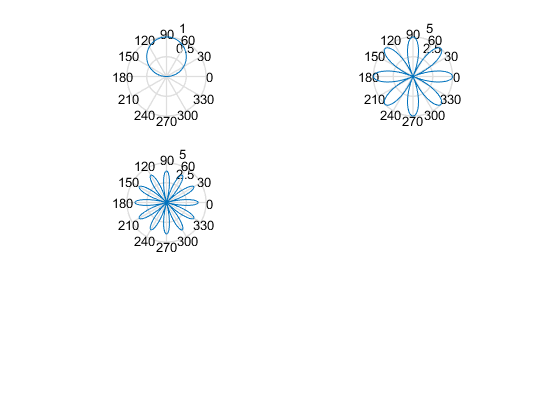

figure()
subplot(3, 2, 1)
polar(x, y)

% arreglo theta desde 0 hasta 2 pi, en paso de 0.01 pi
subplot(3, 2, 2)
theta = 0:0.01*pi:2*pi;
radio = 5 * cos(4*theta);
polar(theta, radio)
% asigne r = 4 cos(6 theta)
subplot(3, 2, 3)
radio = 4 * cos(6 * theta);
polar(theta, radio)

Defina un arreglo theta tal que theta = pi/2:4/5:4.8*pi; Cree un arreglo de seis miembros de unos llamado r. Cree una nueva gráfica polar theta contra r.

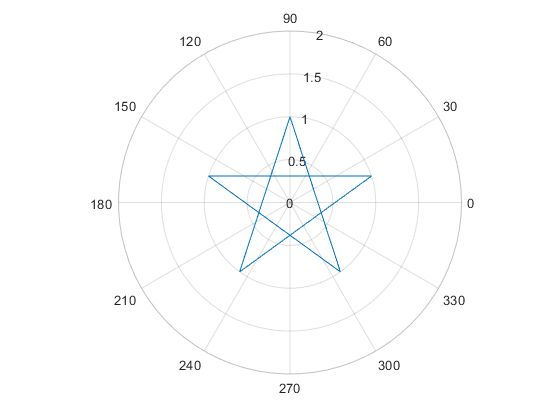


figure()
theta=pi/2:4/5*pi:4.8*pi;
radio=ones(1,6);
polarplot(theta,radio)

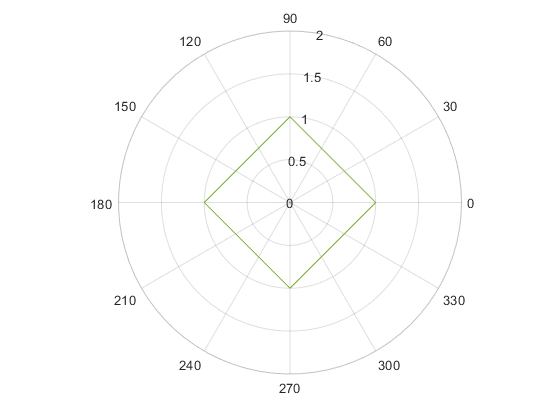

figure
theta= 0:pi/2:2*pi;
radio=ones(5);
polarplot(theta,radio)

### Gráficas logarítmicas

Para la mayoría de las gráficas que se generan, los ejes x y y se dividen en intervalos igualmente espaciados; dichas gráficas se llaman gráficas lineales o rectangulares. Sin embargo, en ocasiones es posible que se quiera usar una escala logarítmica en uno o ambos ejes. Una escala logarítmica (a la base 10) es conveniente cuando una variable varía sobre muchos órdenes de magnitud, porque el amplio rango de valores se **puede graficar sin comprimir los valores más pequeños**. Las gráficas logarítmicas también son **útiles para representar datos que varían exponencialmente**.

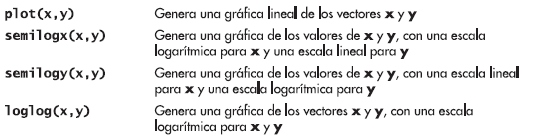

Recuerde que** el logaritmo de un número negativo o de cero no existen**. Si sus datos incluyen estos valores, MATLAB emitirá un mensaje de advertencia y no se graficarán los puntos en cuestión. Sin embargo, generará una gráfica con base en los puntos restantes. Cada uno de los comandos para graficación logarítmica se puede ejecutar con un argumento, como se vio en plot(y) para una gráfica lineal. En estos casos, las gráficas se generan con los valores de los índices del vector y usados como valores x. Como ejemplo, se crearon gráficas de $y=5x^2$ con los cuatro enfoques de escalamiento. Las gráficas lineal (rectangular), semilog en el eje x, semilog en el eje y y log-log se muestran todas en una figura, graficadas con la función subplot en el código siguiente:

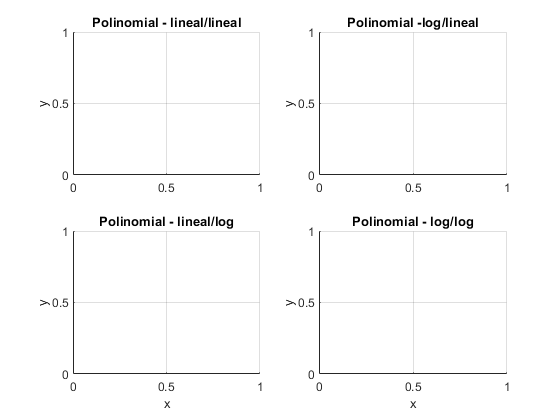

figure
x = 0:0.5:50;
y = 5 *x.^2;

% Gráfica lineal
subplot(2,2,1)
semilogx(x,y)
plot
%...
title('Polinomial - lineal/lineal')
ylabel('y'), grid

% Gráfica semilog en el eje x
subplot(2,2,2)
%...
title('Polinomial -log/lineal')
ylabel('y'), grid

% Gráfica semilog en el eje y
subplot(2,2,3)
% ...
title('Polinomial - lineal/log')
xlabel('x'), ylabel('y'), grid

% Gráfica log-log
subplot(2,2,4)

title('Polinomial - log/log')
xlabel('x'), ylabel('y'), grid

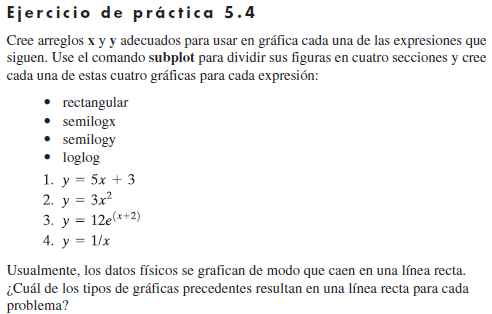

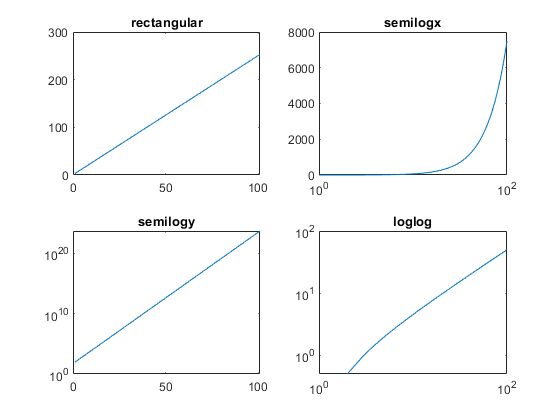

figure
subplot(2,2,1)
plot((5*x+3))
title('rectangular')

subplot(2,2,2)
semilogx(3*(x).^2)
title('semilogx')


subplot(2,2,3)
semilogy(12 *(exp(x+2)))
title('semilogy')


subplot(2,2,4)
loglog(1\x)
title('loglog')

### Gráficas de barras y de pastel

Las gráficas de barra, histograma y de pastel son formas populares para reportar datos.

En la siguiente tabla se puede apreciar algunas de las funciones usadas comúnmente para crear gráficas de barra y de pastel.

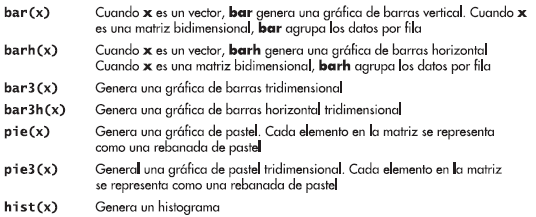

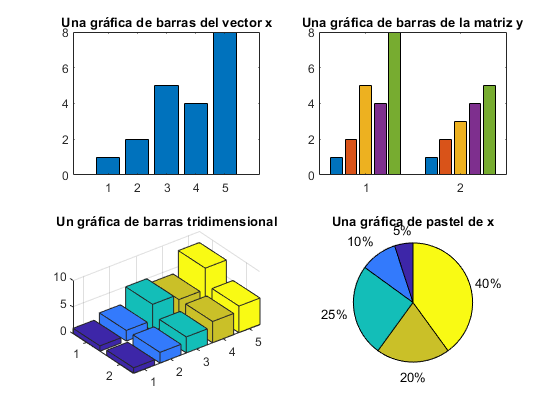

% ejemplos de algunas de estas gráficas
x = [1 2 5 4 8];
y = [x; 1:5];

subplot(2,2,1)
bar(x), title('Una gráfica de barras del vector x')

subplot(2,2,2)
bar(y), title('Una gráfica de barras de la matriz y')

subplot(2,2,3)
bar3(y), title('Un gráfica de barras tridimensional')

subplot(2,2,4)
pie(x), title('Una gráfica de pastel de x')

% agregar ruta de scripts

addpath(genpath('.'))

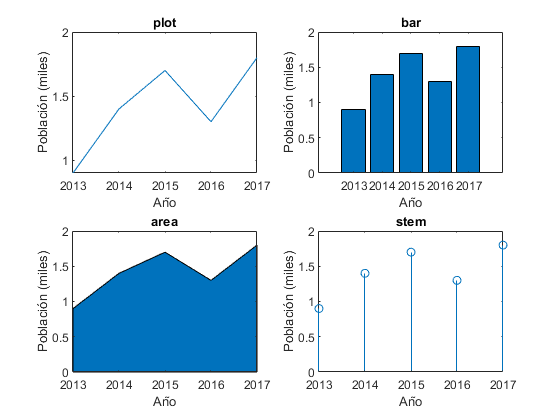


run('EJ_1.m') % varios tipos de gráficas

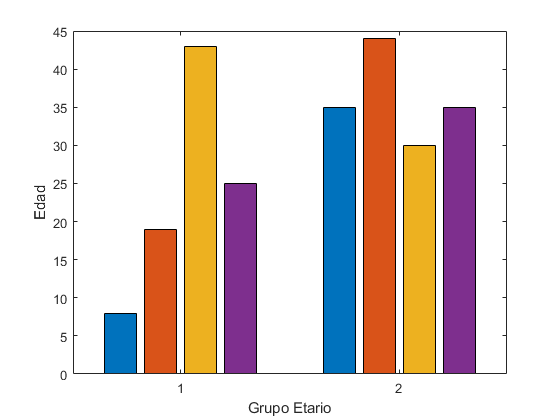

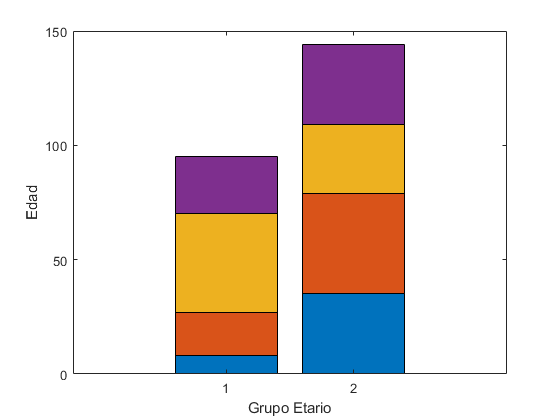

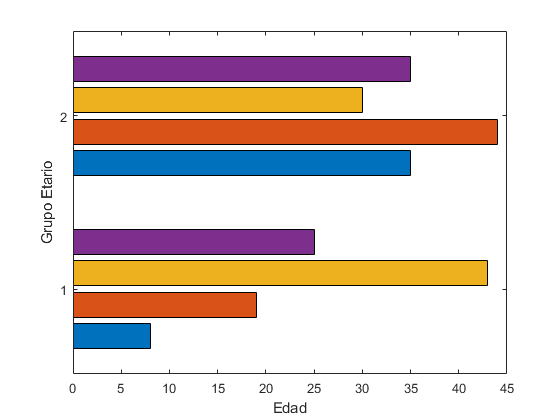

run('EJ_2.m') % ejemplos de barras

### Histogramas

Un histograma es un tipo especial de gráfica particularmente **útil para el análisis estadístico de datos**. Es una gráfica que **muestra la distribución de un conjunto de valores**. En MATLAB, el histograma calcula el número de valores que caen en 10 depósitos (categorías) que están igualmente espaciadas entre los valores mínimo y máximo. Por ejemplo, si se define una matriz x como el conjunto de calificaciones del Final de Introducción a la ingeniería, las calificaciones se podrían representar en un histograma, que se muestra en la siguiente figura y se genera con el siguiente código:

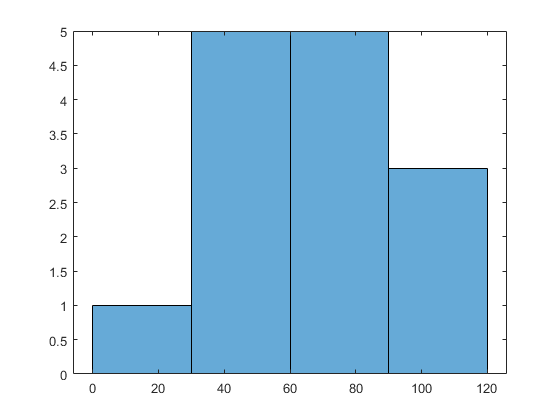

figure()
x = [100, 95, 74, 87, 22, 78, 34, 35, 93, 88, 86, 42, 55, 48];
histogram(x)

El número por defecto de depósitos (bins) es 10, pero si se tiene un gran conjunto de datos, se pueden dividir los datos en más depósitos. Por ejemplo, para crear un histograma con 25 depósitos, el comando sería

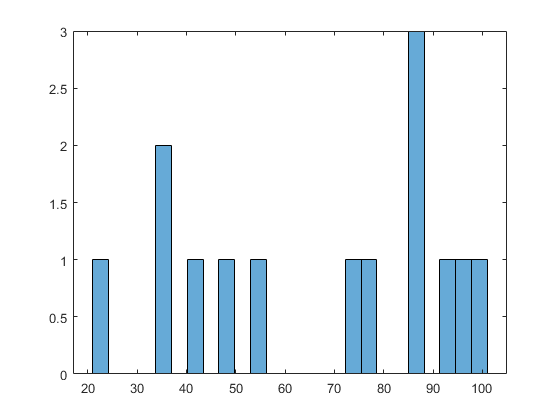

histogram(x, 25)

A =   Histogram with properties:

             Data: [100 95 74 87 22 78 34 35 93 88 86 42 55 48]
           Values: [1 5 5 3]
          NumBins: 4
         BinEdges: [0 30 60 90 120]
         BinWidth: 30
        BinLimits: [0 120]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


% si se establece la función hist igual a una variable los datos que se
% usan en la gráfica se almacenan en A:
A = histogram(x)

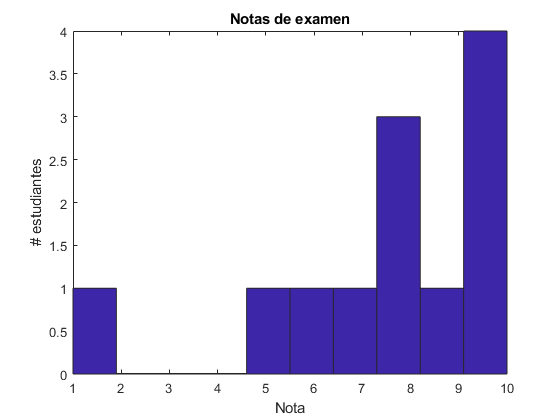

run('EJ_3.m') % ejemplo de histogramas

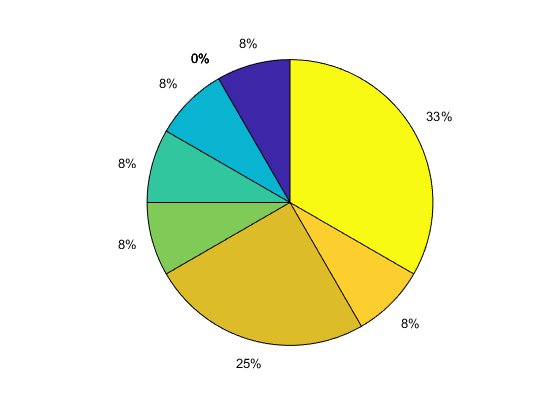

% ahora un gráfico de pasteles
preguntas = [10 8 5 10 10 6 9 7 8 10 1 8];
r= hist(preguntas);
pie(r)

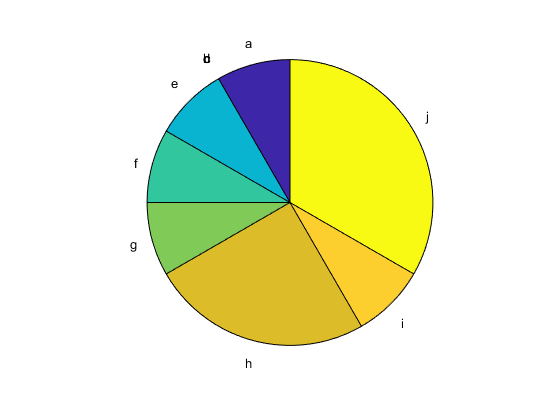

% si no se quieren ver los porcentajes
pie(r,{'a','b','c','d','e','f','g','h','i','j'})

### Graficas x-y con dos ejes y

A veces es útil sobreponer dos gráficas x-y en la misma figura. Sin embargo, si los órdenes de magnitud de los valores y son muy diferentes, puede ser difícil ver cómo se comportan los datos. Considere, por ejemplo, una gráfica de  $\textrm{sen}\left(x\right)$ y $e^x$ dibujadas en la misma figura. 

Los resultados, obtenidos con el siguiente código, se muestran en la siguiente figura:

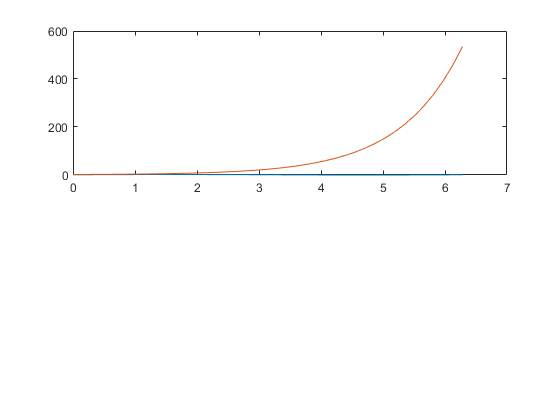

x = 0:pi/20:2*pi;
primer_eje_y = sin(x);
segundo_eje_y = exp(x);
subplot(2,1,1)
plot(x, primer_eje_y, x, segundo_eje_y)

La gráfica de sen(x) parece que corre en línea recta a lo largo de x = 0, debido a la escala. La función **plotyy** le permite crear una gráfica con dos ejes y, el de la izquierda para el primer conjunto de pares ordenados y el de la derecha para el segundo conjunto de pares ordenados:

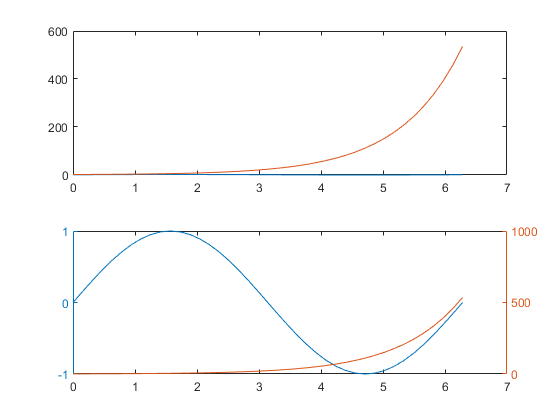

subplot(2,1,2)
plotyy(x, primer_eje_y, x, segundo_eje_y)

La función plotyy puede crear algunos tipos diferentes de gráficas al agregar una cadena con el nombre del tipo de gráfica después del segundo conjunto de pares ordenados. 

En la siguiente figura, las gráficas se crearon con el siguiente código y tienen un eje con escala logarítmica:

figure()
subplot(2,1,1)
plotyy(x, primer_eje_y, x, segundo_eje_y, 'semilogy')

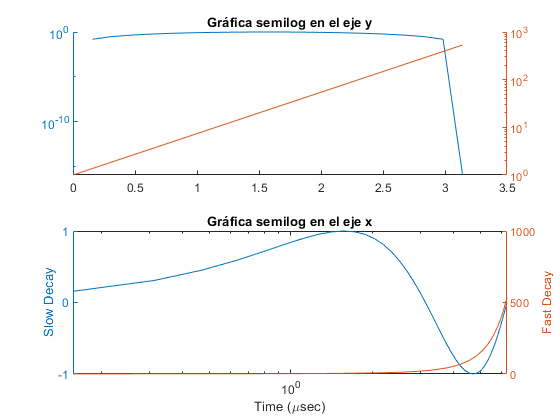

title('Gráfica semilog en el eje y')
subplot(2,1,2)
[hAx,hLine1,hLine2] = plotyy(x, primer_eje_y, x, segundo_eje_y, 'semilogx');
title('Gráfica semilog en el eje x')
xlabel('Time (\musec)')
ylabel(hAx(1),'Slow Decay') % left y-axis 
ylabel(hAx(2),'Fast Decay') % right y-axis

Actualización: En las nuevas versiones de MATLAB se recomienda utilizar yyaxis

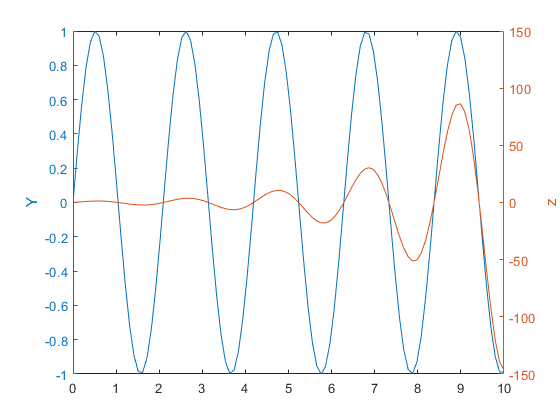

figure
x = linspace(0,10);
y = sin(3*x);
yyaxis left
plot(x,y)
ylabel('Y')

z = sin(3*x).*exp(0.5*x);

yyaxis right
plot(x,z)
ylim([-150 150])
ylabel('z')

**Reto**: 

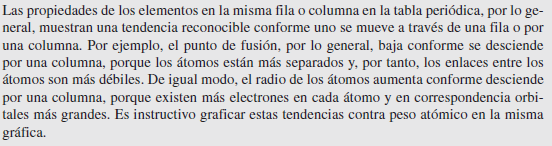

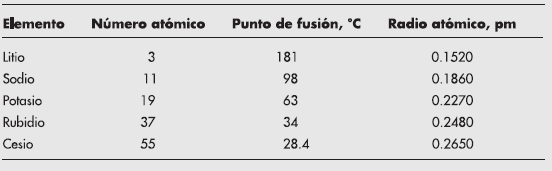

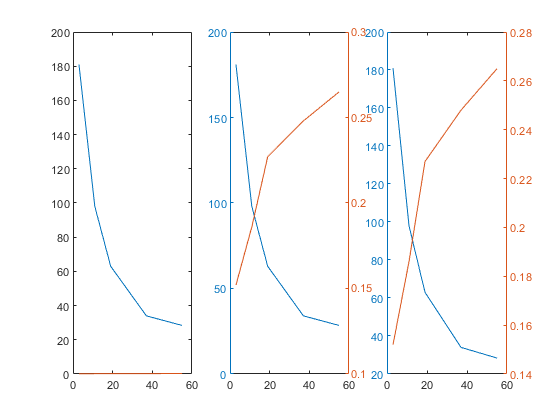

% datos
clear, clc
figure
% Definición de variables
numero_atomico = [3 11 19 37 55];
punto_fusion = [181 98 63 34 28.4];
radio_atomico = [0.1520 0.1860 0.2270 0.2480 0.2650];


% Crear la gráfica con dos lineas en la misma escala

subplot(1,3,1)
plot(numero_atomico,punto_fusion,numero_atomico,radio_atomico)
% Crear la gráfica con dos diferentes escalas y

subplot(1,3,2)
plotyy(numero_atomico,punto_fusion,numero_atomico,radio_atomico)
subplot(1,3,3)

%yyaxis

yyaxis left
plot(numero_atomico,punto_fusion)
yyaxis right
plot(numero_atomico,radio_atomico)

### Grafícas de función

La función fplot le permite graficar una función sin definir arreglos de valores x y y correspondientes.

Por ejemplo

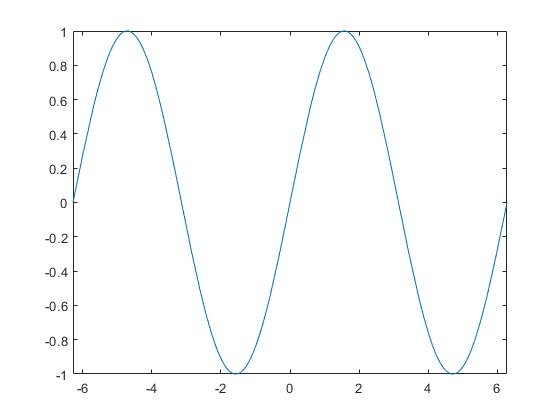

figure
fplot('sin(x)', [-2*pi,2*pi])

### Gaficas tridimensionales

MATLAB ofrece una variedad de comandos para gráficas tridimensionales, muchas de las cuales se mencionan en la siguiente tabla

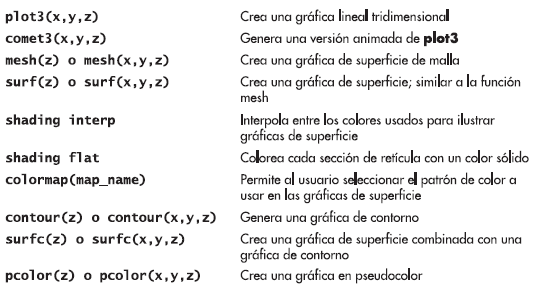

#### Gráfica lineal tridimensional

La función plot3 es similar a la función plot, excepto que acepta datos en tres dimensiones. Sin embargo, en lugar de sólo proporcionar vectores x y y, el usuario también debe proporcionar un vector z. Entonces estas tripletas ordenadas se grafican en un espacio de tres dimensiones y se conectan con líneas rectas. Por ejemplo

figure
x = linspace(0, 10*pi, 1000);
y = cos(x);
z = sin(x);
% ...
grid
xlabel('ángulo'), ylabel('cos(x)'), zlabel('sen(x)'), title('Un resorte')

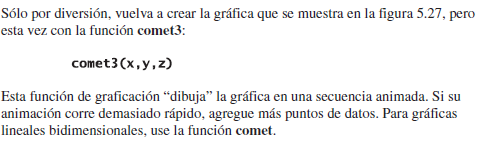

comet3(x,y,z)

Unrecognized function or variable 'x'.

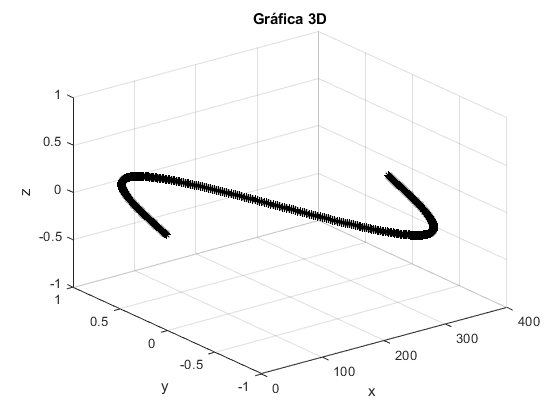

% otros ejemplos de gráficas 3D (diapositiva 30)
figure
run("ejemplosdiapositivas\Ej5_3D.m")

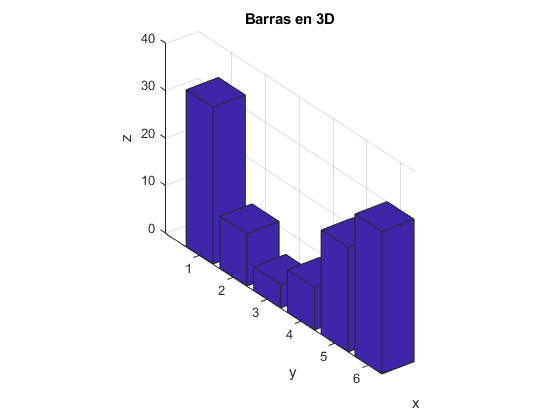

run("ejemplosdiapositivas\Ej6_BAR3.m")

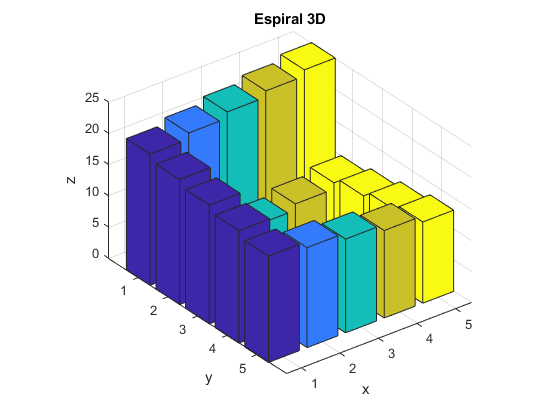

figure
run("ejemplosdiapositivas\Ej7_Spiral.m")

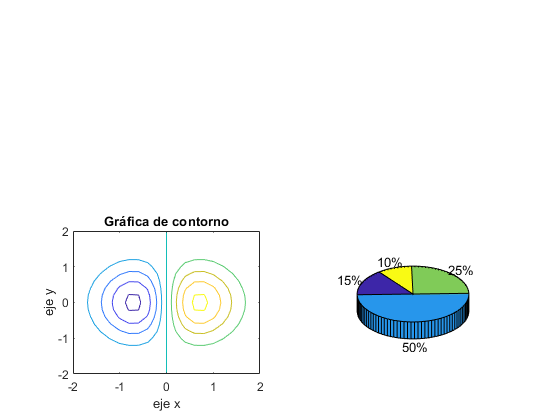

pie3([3 10 5 2])

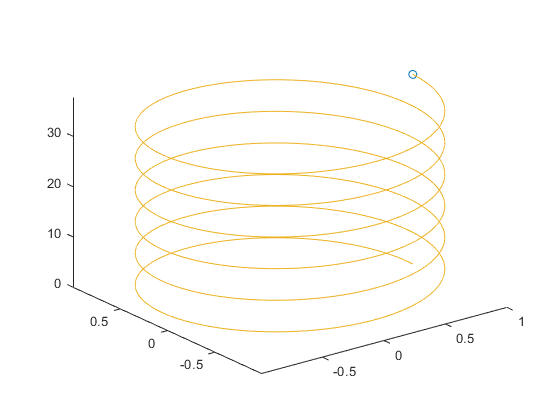

run("ejemplosdiapositivas\Ej8_comet.m") % ejecutar desde el script

#### Gráficas de superficie

Las gráficas de superficie le permiten representar datos como una superficie. Se experimentará con dos tipos de gráficas de superficie: gráficas mesh y gráficas surf.

Gráficas mesh

Existen muchas formas de usar las gráficas mesh (malla). Se pueden usar para dar buen efecto a una matriz bidimensional sencilla $m\;x\;n$. En esta aplicación, el valor en la matriz representa el valor z en la gráfica. Los valores x y y se basan en las dimensiones de la matriz. Tome, por ejemplo, la siguiente matriz muy simple:

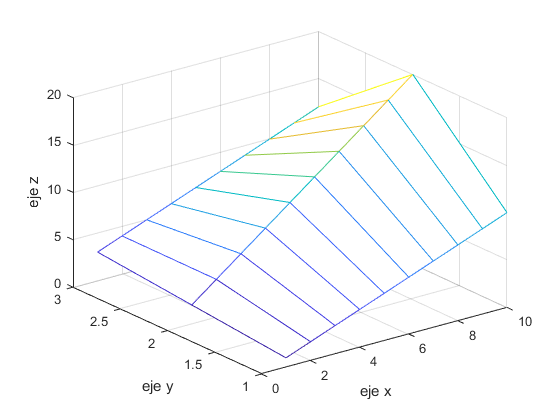

z = [1:10; 2:2:20; 3:12];

figure
mesh(z)
xlabel('eje x')
ylabel('eje y')
zlabel('eje z')

La función mesh también se puede usar con tres argumentos: mesh(x,y,z). En este caso, x es una lista de coordenadas x, y es una lista de coordenadas y, y z es una lista de coordenadas z.

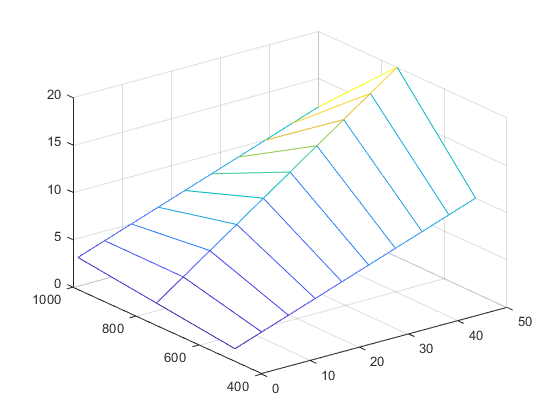

figure
x = linspace(1, 50, 10);
y = linspace(500, 1000, 3);
z = [1:10; 2:2:20; 3:12];
mesh(x,y,z)

El vector x debe tener el mismo número de elementos que el número de columnas en el vector z; el vector y debe tener el mismo número de elementos que el número de filas en el vector z.

#### Gráficas surf

Las gráficas surf son similares a las gráficas mesh, pero surf crea una superficie tridimensional colorida en lugar de una mesh. Los colores varían con el valor de z.

El comando surf toma la misma entrada que mesh: una sola entrada (por ejemplo, surf(z), en cuyo caso usa los índices fila y columna como coordenadas x y y), o tres matrices.

Se puede crear una superficie más complicada al calcular los valores de Z:

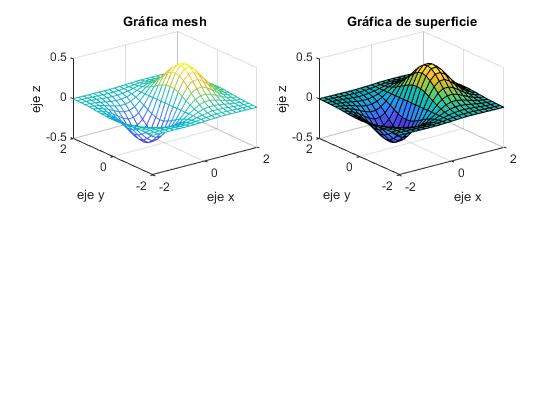

figure
x = [-2:0.2:2];
y = [-2:0.2:2];
[X, Y] = meshgrid(x, y);
Z = X.*exp(-X.^2 - Y.^2);

subplot(2,2,1)
mesh(X,Y,Z)
title('Gráfica mesh'), xlabel('eje x'), ylabel('eje y'), zlabel('eje z')

subplot(2,2,2)
surf(X,Y,Z)
title('Gráfica de superficie'), xlabel('eje x'), ylabel('eje y'), zlabel('eje z')

#### Gráficas de contorno

Las gráficas de contorno son representaciones bidimensionales de superficies tridimensionales.

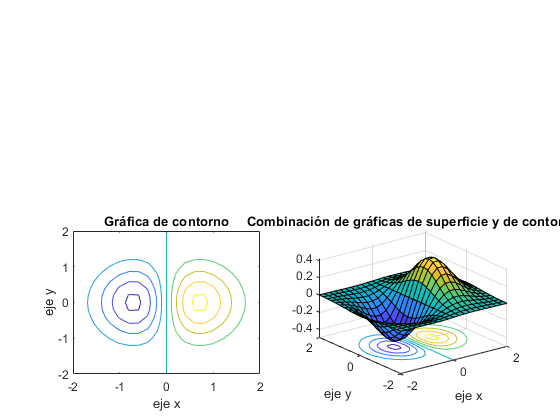

figure
subplot(2,2,3)
contour(X,Y,Z)
xlabel('eje x'), ylabel('eje y'), title('Gráfica de contorno')

subplot(2,2,4)
surfc(X,Y,Z)
xlabel('eje x'), ylabel('eje y'), title('Combinación de gráficas de superficie y de contorno')